clear variables

load leftPic.mat
load rightPic.mat

% Device-1  Right Camera
% Device-2  Left  Camera
Image_right = snapshot1;
Image_left = snapshot2;

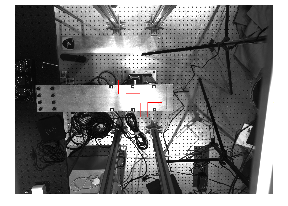

detectorObjects.blobAnalysis = vision.BlobAnalysis('BoundingBoxOutputPort', true,'AreaOutputPort', true,'CentroidOutputPort', true, ...
    'MinimumBlobArea', 200, 'MaximumBlobArea', 1000,'MaximumCount', 50,'PerimeterOutputPort',true);

img = Image_left;

[centroids_1, bbox_new] = detectBlobs(detectorObjects,img);

frame = insertShape(img,"rectangle",bbox_new,"LineWidth",4,"Color","blue");
imshow(frame)

% 我们完全可以定位一个更大的候选框，用于物体跟踪
bbox_1(:,1) = bbox_new(:,1)-100;
bbox_1(:,2) = bbox_new(:,2)-100;
bbox_1(:,3) = bbox_new(:,3)+200;
bbox_1(:,4) = bbox_new(:,4)+200;

frame = insertShape(img,"rectangle",bbox_1,"LineWidth",4,"Color","red");
imshow(frame)

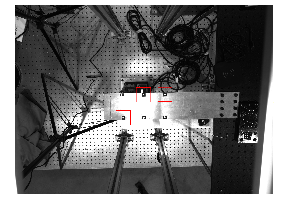

img = Image_right;
imshow(img);

[centroids_2, bbox_new] = detectBlobs(detectorObjects,img);

frame = insertShape(img,"rectangle",bbox_new,"LineWidth",4,"Color","blue");
imshow(frame)

% 我们完全可以定位一个更大的候选框，用于物体跟踪
bbox_2(:,1) = bbox_new(:,1)-100;
bbox_2(:,2) = bbox_new(:,2)-100;
bbox_2(:,3) = bbox_new(:,3)+200;
bbox_2(:,4) = bbox_new(:,4)+200;

frame = insertShape(img,"rectangle",bbox_2,"LineWidth",4,"Color","red");
imshow(frame)

load stereoMatrix.mat;

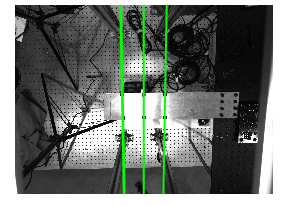

[pt_num_left,~] = size(centroids_1);
[pt_num_right,~] = size(centroids_1);

figure;
imshow(Image_right);
hold on;

F_L2R = stereoParams.FundamentalMatrix;

[~,col] = size(Image_right);

%画左图像标志点在右图像中的极线
for i = 1 : pt_num_left
    tmp_pts = [centroids_1(i, 1), centroids_1(i, 2), 1];
    epipolarline = F_L2R * tmp_pts';
    A1 = epipolarline(1);
    B1 = epipolarline(2);
    C1 = epipolarline(3);
    x0 = 1;
    y0 = -A1 / B1 * x0 - C1 / B1;
    x1 = col;
    y1 = -A1 / B1 * x1 - C1 / B1;
     % 绘制极线
    plot([x0, x1], [y0, y1], 'g-', 'LineWidth', 1);
end

matched_pts = zeros(pt_num_right, 2);  % 预分配 matched_pts 的大小
matched_num = 0;  % 记录匹配的点对数量
for i = 1 : pt_num_right       
    min_distance = 100000;
    index = 0;  
    % 计算右图像中标志点到每条极线的距离
    for k = 1 : pt_num_left
        tmp_pts = [centroids_1(k, 1), centroids_1(k, 2), 1];
        epipolarline = F_L2R * tmp_pts';
        A1 = epipolarline(1);
        B1 = epipolarline(2);
        C1 = epipolarline(3);
        distance = abs(A1 * centroids_2(i, 1) + B1 * centroids_2(i, 2) + C1) / (sqrt(A1^2 + B1^2));
        if distance < min_distance
            min_distance = distance;
            index = k;
        end
    end
    min_distance
    if min_distance < 10  % 设定阈值，去除不存在匹配的非公共点
       matched_num = matched_num + 1;
       matched_pts(matched_num, :) = [index, i];
    end
end

min_distance = 0.4526

min_distance = 0.4792

min_distance = 0.6719

min_distance = 0.8323

min_distance = 0.6038

min_distance = 0.3471

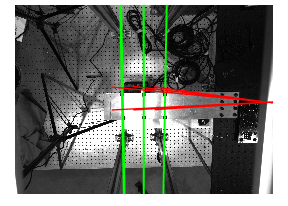


matched_pts = matched_pts(1:matched_num, :);  % 裁剪 matched_pts，保留有效的匹配点对

for i = 1 : matched_num
    matched_left_pt = centroids_1(matched_pts(i,1), :);
    matched_right_pt = centroids_2(matched_pts(i,2), :);
    line([matched_left_pt(1), matched_right_pt(1)+col],[matched_left_pt(2), matched_right_pt(2)], 'linewidth', 0.8, 'color', 'r');
end

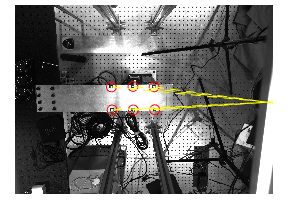

% 将正确匹配的点对保存
DD = centroids_1(matched_pts(:, 1), :);
BB = centroids_2(matched_pts(:, 2), :);

showMatchedFeatures(Image_left,Image_right,DD,BB,"montage",PlotOptions=["ro","go","y--"])

bboxDevice1 = bbox_2;
bboxDevice2 = bbox_1;
centroidsDevice2 = centroids_1;
centroidsDevice1 = centroids_2;

boxInit = struct('box_1',bboxDevice1,'box_2',bboxDevice2);
coordinateInit = struct('centroids_1',centroidsDevice1,'centroids_2',centroidsDevice2);

matchInit = matched_pts;

visionInit = struct('boxInit',boxInit,'coordinateInit',coordinateInit,'matchInit',matchInit,'stereoMatrix',stereoParams);
save('K:\W2-DT\DTplate\Project_1_ForceIdentification\OwnCode\Vision\data\visionInit.mat','visionInit');

function [centroids_new, bbox_new] = detectBlobs(detectorObjects, frame)
% Expected uncertainty (noise) for the blob centroid.

    frame_gray = im2gray(frame);
    fig_binarize = imbinarize(frame_gray,0.9);
    
    [area,centroids,bbox,Perimeter] = detectorObjects.blobAnalysis.step(fig_binarize);
    
    selectedBlobs = (3.5 <(Perimeter.^2)./(double(area)*pi)) & ((Perimeter.^2)./(double(area)*pi) < 4.5);
    bbox_new = bbox(selectedBlobs, :);
    centroids_new = centroids(selectedBlobs, :);
end